# ME: 6240 Long Homework 4

EKF-SLAM!

4-20-2021 (nice!)

## Michael Swafford

#### Consider the robot and the environment from the SLAM demonstration animation shown in class (on ICON in the Lecture Notes and Handouts Folder). Using EKF-SLAM (or an algorithm of your choosing), you are essentially aiming to recreate that animation.

#### We are going to use a revised version of the robot's velocity-based process model presented in class. This is because the translated velocity, $V_m$, and rotational velocity, $\omega_m$, switch off. Meaning when $V_m = 0$, $\omega_m \neq 0$ and vice versa. The process model you should use is the following,


$$\pmatrix{x_{k+1}\cr y_{k+1}\cr \theta_{k+1}} = \pmatrix{x_{k}\cr y_{k}\cr \theta_{k}}+\pmatrix{V_{m_k}\Delta t cos(\theta_k)\cr V_{m_k}\Delta t sin(\theta_k)\cr \omega_{m_k}\Delta t}$$


#### where $\Delta t = 0.1 sec$, $V_m$ has associated noise $v_m \sim \mathcal{N}(0,\sigma_V=0.005 m/s)$, and $\omega_m$ has associated noise $v_\omega \sim \mathcal{N}(0,\sigma_\omega=0.0045 rad/s)$. The process noise for this process model is a familiar one, 

#### 
$$Q = \pmatrix{\sigma_V^2 & 0\cr 0 & \sigma_\omega^2}$$


#### Note that with the new process model, you will need to rederive some of the Jacobians. The Measurements provided are range, r, and bearing, $\phi$, which means the observation model you should use is the same one that has been used in class. The measurement noises for these sensors follow a normal distribution, $w_r \sim \mathcal{N}(0,\sigma_r=0.075 m)$and $w_\phi \sim \mathcal{N}(0,\sigma_\phi=0.075 m)$. Both sensors are sampling simultaneously at 2 Hz ($\Delta t_m = 0.5$ seconds).

#### The MATLAB data file contains a variable V_m that contains the translational velocities and another variable OMEGA_m that contains the angular velocities. The file contains another variable z for which the first column contains the times when the measurements were made, the second column contains the landmark ID, the thrid column contains the range measurements, and the forth column contains the bearing measurements. Another variable lndmrk contains the true locations of the landmarks for which the first column contains the x-position and the second column contains the y-position. The index for the landmark corresponds to the landmark's ID.

# 1) Write your own pseudocode describing how the state and error covariance are propagated and updated. Be sure to include the steps required to augment the state vector and error covariance when a new landmark is observed. While not required, it might also be a good idea to keep track of the sizes of the various vecotrs and matrices for reference when you go to implement your pseudocode in the next question.

# For the update step, describe the approach for both sequential updates and batch updates.

## Pseudocode for EKF-SLAM

% In simple terms this program will use an Extended Kalman Filter to localize a mobile robot in an environemtn while simultaneously creating a map

%of said environment from detected landmarks.

## 0) Initialize State Vector, Covariance, Jacobians, 

## Initial State Vector: $\pmatrix{x_{0}=0 \cr y_{0} = 0 \cr \theta_{0} = 0}$, Initial Covariance: $\pmatrix{P_{xx} = (0)_{3x3}}$, 

## Jacaobians $F_{x_0} = I_{3x3} $, $G_{k=0} = \pmatrix{0}_{3x2}$, $F_{k = 0} = \pmatrix{0}_{3x3}$, $F_0 = \pmatrix{F_{k=0}}$, $L_{x_0} = \pmatrix{0}_{2x3}$, $L_{z_0} = \pmatrix{0}_{2x1}$

## Other $Q = \pmatrix{\sigma_V^2 & 0\cr 0 & \sigma_\omega^2}
$, $L(x_k,z_k) = \pmatrix{0}_{2x2}$, $R = \pmatrix{\sigma_{w_r}^2 & 0\cr 0 & \sigma_{w_{\phi}}^2}$

## 1) Propagation (all equations are calculated for every time step k)

##  
$$f(X_k,u_k) = \pmatrix{x_{k}\cr y_{k}\cr \theta_{k}}+\pmatrix{V_{m_k}\Delta t cos(\theta_k)\cr V_{m_k}\Delta t sin(\theta_k)\cr \omega_{m_k}\Delta t} \equiv X_{k+1}$$


## $X_{k+1} = X_k +F_x^T*f(X_k,u_k)$, where $F_x^T = \pmatrix{I_{3x3}\cr 0_{2nx3}}$,

## $P_{k+1} = FP_kF^T+F_x^TG_kQG_k^TF_x$, where $F = \pmatrix{F_k & 0_{3x2n}\cr 0_{2nx3} & I_{2nx2n}}$, $F_k=\frac{\partial f(X_k,u_k)}{\partial X_k} = \pmatrix{1 & 0 & -V_{m_k}\Delta t sin(\theta_k)\cr 0 & 1 & V_{m_k}\Delta t cos(\theta_k)\cr 0 & 0 & 1}$, $G_k=\frac{\partial f(X_k,u_k)}{\partial u_k} = \pmatrix{\Delta t cos(\theta_k) & 0\cr \Delta t sin(\theta_k) & 0\cr 0 & \Delta t}$,

## Note: $P_{k+1} \equiv \pmatrix{P_{xx_{3x3}} & P_{xm_{3x2n}}\cr P_{mx_{2nx3}}& P_{mm_{2nx2n}}}$

## 2) Check for an avilable measurement from z. Done by checking time stamp of simulation (k) and measurement time stamp (for k in data.z.time)

## 2a) If no measurement is available go back to 1

## 2b) If a new landmark is detected:

## 2b.1) Increment a landmarkID counter variable from 0 to 1, then do the following

## 2b.2) Define new landmark's global position: $L(X_k,z_k)=\pmatrix{l_{new,x}\cr l_{new,y}} = \pmatrix{x_{k+1}\cr  y_{k+1}}+\pmatrix{r_kcos(\phi_k+\theta_k)\cr r_ksin(\phi_k+\theta_k)}$

## 2b.3) Augment both the state vector: $X_{aug,k+1} = \pmatrix{X_{k+1}\cr l_{new,x}\cr l_{new,y}}$ and the error-covariance: $P_{aug,k+1} = \pmatrix{P_{xx_{3x3}} & P_{xm_{3x2n}} & P_{xl_{3x2}}\cr P_{mx_{2nx3}}& P_{mm_{2nx2n}} & P_{ml_{2nx2}}\cr P_{lx_{2x3}}&P_{lm_{2x2n}}&P_{ll_{2x2}}}$, where $P_{lx}=P_{xl}^T = L_xP_{xx}$, $P_{lm}=P_{ml}^T=L_xP_{xm}$, and $P_{ll}=L_xP_{xx}L_x^T+L_zRL_z^T$. $L_x =\frac{\partial L(X_k,z_k)}{\partial X_k}= \pmatrix{1&0&-r_ksin(\phi_k+\theta_k)\cr 0&1&r_kcos(\phi_k+\theta_k)}$and $L_z = \pmatrix{cos(\phi_k+\theta_k) & -r_ksin(\phi_k+\theta_k)\cr sin(\phi_k+\theta_k)&r_kcos(\phi_k+\theta_k)}$.

##  2c) If a landmark has already been detected:

## 2c.1) Increment the landmarkID counter for the identified landmark (counter will serve as the jth observation). 

## ****Note: this is the sequential version where each measurment at a given time step is calculated independent of the others. If this were to be done in batch each step would use a vector of all of the landmarks observed at a given timestep.**

## 2c.2) Estimate what the measurement should be: $\delta_j = \pmatrix{l_{i,x}-x_{k+1}\cr l_{i,y}-y_{k+1}}$, (i refers to the landmark ID) and $q_j = \delta_j^T\delta_j$. Then $\hat z_j = \pmatrix{\sqrt{q_j}\cr atan2(\delta_{j,y},\delta{j,x})-\theta_{k+1}}=\pmatrix{\hat r\cr \hat \phi}=h(X_{k+1},l_i)$

## 2c.3) Get jacobian of $h(X_{k+1},l_i)$ with respect to both components:

## 
$$H_{xl} = \frac{1}{q_j}\pmatrix{-\sqrt{q_j}\delta_{j,x}&-\sqrt{q_j}\delta_{j,y}&0&\sqrt{q_j}\delta_{j,x}&\sqrt{q_j}\delta_{j,y}\cr \delta_{j,y} & -\delta_{j,x} & -q_j & -\delta_{j,y}&\delta_{j,x}}$$


## 2c.4) Create a transform H: $H_{j_{2x(2n+3)}} = H_{xl}F_z$, where $F_z = \pmatrix{ 1&0&0& &0&0& \cr 0&1&0 & & 0 &  0 & \cr 0&0&1 & 0_{5x2(i-1)} & 0 &  0 & 0_{5x2(n-i)}\cr 0&0&0& & 1&0& \cr 0&0&0& &0 &1 }$,

## 2c.5) Finally calculate the Kalman Gain and update the state-vector and error-covariance

## 
$$K_{k_{(2n+3)x2}} = P_{k+1}^-H_j^T(H_jP_{k+1}^-H_j^T+R)^{-1}$$


## 
$$X_{k+1}^+ = X_{k+1}^-+K_k(z_{k,j}-\hat z_j) $$


## 
$$P_{k+1}^+ = (I-K_kH_j)P_{k+1}^-$$


# 2) Implement you pseoducode in MATLAB. Provide a plot of the robot's estimated trajectory throughout the simulation, the final estimated locations of the landmarks, and the true estimated locations of the landmarks. Run the simulation twice: first with sequential updates and then with batch updates. Do you notice any changes in the algorithm's performance? Why might the batch updates be preferable?

clear all

%Load in the data
load("slam-data.mat")

%let's put everything into a structure to make our life easier
data.time = z(:,1)/10; %weirdness (gap between is 0.5sec)
data.z.landID = z(:,2);
data.z.range = z(:,3);
data.z.bearing = z(:,4);
data.land.ID = linspace(1,length(lndmrk),length(lndmrk))';
data.land.x = lndmrk(:,1);
data.land.y = lndmrk(:,2);
%zorg = z; %for debugging
clear z lndmark %get rid of duplicate variables
%Initialize all the vars
deltaT = 0.1;
tEnd = length(V_m)*deltaT;
t = 0:deltaT:tEnd;
pos_k = zeros(3,length(t)+1); 
x_k = zeros(3,1); %x y theta + (lx ly)*10 , 0:end-time
Pxx = zeros(3,3);
% Pxm = zeros(3,1);
% Pmm = 0;
P_k = [Pxx];
G_k = zeros(2,3);
F_k = zeros(3,3);
n = 0; %number of landmarks detected
idCount = [0];
idCount_check = [0];
L = [0;0]; %new landmark
delta = zeros(2,1); %landmark update
sigma_v = 0.005;
sigma_w = 0.0045;
Q =[sigma_v^2 sigma_w^2].*eye(2);
sigma_r = 0.075;
sigma_b = 0.075;
R = [sigma_r^2 sigma_b^2].*eye(2);
tol = eps(tEnd*2); %precision for floating point
% %for IDcount debugging
% for x=1:length(data.z.landID)
%     y = data.z.landID(x);
%     if idCount_check(y) == 0
%         idCount_check(y) = 1;
%         idCount_check = [idCount_check 0];
%     else
%         idCount_check(y) = idCount_check(y)+1;
%     end
% end
% idCount_check(end)=[];

%animation time
Time = t;
dt=mean(diff(Time));
% for error cov x and y axis
locations = {'X','Y','\theta'};
%set figure
f1 = figure;
%plot side by side
%covariance plot
subplot(1,2,1)
cov = heatmap(locations(1:3),locations(1:3),P_k(1:3,1:3),'ColorMethod','max');
%cov.ColorLimits = [0.01 0.001];
ax = gca;
axp = struct(ax);

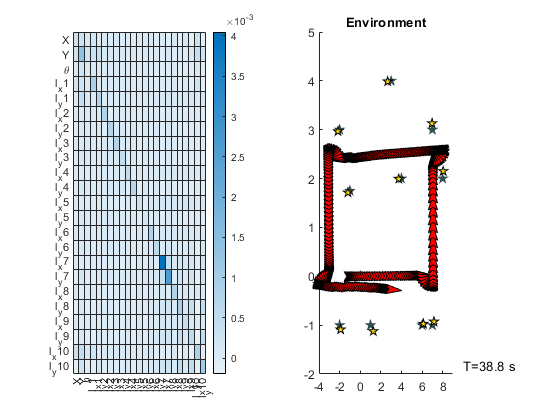

axp.Axes.XAxisLocation = 'top';
grid on
subplot(1,2,2)
hold on
%landmark plot set up
size = 50;
%plot true land marks
scatter(data.land.x,data.land.y,size,'MarkerFaceColor','#2F4F4F',"MarkerEdgeColor",'#2F4F4F','Marker','pentagram')
land_sc = scatter(L(1,:),L(2,:),size,'MarkerFaceColor','#FFD700',"MarkerEdgeColor",'#000000','Marker','pentagram');
title("Environment")
ylim([min(data.land.y)-1 max(data.land.y)+1])
xlim([min(data.land.x)-2 max(data.land.x)+1])
%For time stamp display
x1=xlim;
yl=ylim;
Tstamp=text(x1(2)+1,yl(1),['T=' num2str(t(1)) ' s'],'HorizontalAlignment','left','VerticalAlignment','Bottom');
%
FramerateDivisor=round(1/(deltaT*30));

[fname pname]=uiputfile('*.avi','Select Folder and Filename for Video Export');
vid=VideoWriter([pname fname]);
open(vid);

for i=1:length(t)-1
    %update position
    pos_k(:,i) = x_k(1:3,i);
    %calculate input
    f = [V_m(i)*deltaT*cos(pos_k(3,i));V_m(i)*deltaT*sin(pos_k(3,i));OMEGA_m(i)*deltaT];
    %update
    pos_k(:,i+1) = pos_k(:,i)+f;
    %update state
    Fx = [eye(3);zeros(2*n,3)];
    x_k(:,i+1) = x_k(:,i) + Fx*(f);
    %jacobian of f wrt to U
    G_k = [deltaT*cos(pos_k(3,i)) 0;deltaT*sin(pos_k(3,i)) 0; 0 deltaT];
    %jacobian of f wrt to x
    F_k = [1 0 -V_m(i)*deltaT*sin(pos_k(3,i));0 1 V_m(i)*deltaT*cos(pos_k(3,i)); 0 0 1];
    F = [F_k zeros(3,2*n);zeros(2*n,3) eye(2*n)];
    G = [G_k*Q*G_k' zeros(3,2*n);zeros(2*n,3) zeros(2*n)];
    %Error Cov
    P_k = F*P_k*F'+ G;
    %check for an available measurement
    for k=1:length(data.time)        
        T = abs(t(i)-data.time(k)); %need this for floating point error reasons
        %fprintf("T = %.4f at i = %d for k = %d\n",T,i,k) %for tol debugging
        if T < tol
            %fprintf("t(i) = %.2f at i = %d and data.time(k) = %.2f at k =
            %d\n",t(i),i,data.time(k),k) %for time debugging
            %get the landmarkID
            id = data.z.landID(k);
            %if the landmark has been detected
            if idCount(id) == 0
                %fprintf("New Landmark %d\n",id)
                %increase number of landmarks
                n=n+1;
                %add landmark
                L(:,n) = [pos_k(1,i)+data.z.range(k)*cos(data.z.bearing(k)+pos_k(3,i));pos_k(2,i)+data.z.range(k)*sin(data.z.bearing(k)+pos_k(3,i))]; 
                %add Landmark to state vector
                sz = 2;
                temp = zeros(sz,i+1);
                x_k = [x_k;temp];
                x_k(end-1:end,i+1) = L(:,n); 
                %update Error Cov
                Lx = [1 0 -data.z.range(k)*sin(data.z.bearing(k)+pos_k(3,i)); 0 1 data.z.range(k)*cos(data.z.bearing(k)+pos_k(3,i))];
                
                if n == 1
                    Plx = zeros(2);
                    Plm = zeros(2,1);
                else
                    Plx = Lx*P_k(1:3,1:3); %pull Pxx
                    Plm = Lx*P_k(1:3,4:end); %pull Pmx
                end
                Lz = [cos(data.z.bearing(k)+pos_k(3,i)) -data.z.range(k)*sin(data.z.bearing(k)+pos_k(3,i)); sin(data.z.bearing(k)+pos_k(3,i)) data.z.range(k)*cos(data.z.bearing(k)+pos_k(3,i))];
                Pll = Lx*Pxx*Lx' + Lz*R*Lz';
                P_k = [P_k [Plx'; Plm']; [Plx Plm Pll]]; %augment Error cov
                L = [L zeros(2,1)]; %add col to l
                %detected(id) =  true;
                idCount(id) = 1;
                %detected = [detected false]; %add space for another landmark 
                idCount = [idCount 0];
                %add to labeling array
                locations = [locations strcat(['l_x',num2str(n,'%d')])];
                locations = [locations strcat(['l_y',num2str(n,'%d')])];
                %locations = categorical(locations); %make it categorical
                
            else
                idCount(id) = idCount(id)+1;
                count = idCount(id); %make life easy
                %fprintf("Landmark %d has been seen %d times...updating model\n",id,count)
                delta = L(:,id)- x_k(1:2,i+1);
                q = delta'*delta;
                zhat = [sqrt(q);atan2(delta(2),delta(1))-x_k(3,i+1)];
                Hxl = [-sqrt(q)*delta(1) -sqrt(q)*delta(2) 0 sqrt(q)*delta(1) sqrt(2)*delta(2); delta(2) -delta(1) -q -delta(2) delta(1)]/q;
                temp = zeros(5,2*(id-1));
                temp1 = zeros(5,2*(n-id));
                Fz = [[eye(3);zeros(2,3)] temp [zeros(3,2);eye(2)] temp1];
                H = Hxl*Fz;
                Kgain = P_k*H'*inv(H*P_k*H'+R);
                z = [data.z.range(k);data.z.bearing(k)];
                x_k(:,i+1) = x_k(:,i+1)+Kgain*(z-zhat);
                %pull landmark updates
                for j=1:n
                    L(:,j) = x_k(4+2*(j-1):5+2*(j-1),i+1);
                    %disp(L)
                end
                P_k = (eye(length(Kgain))-Kgain*H)*P_k;
                
            end
            
        end
    end
    
    %animation stuff
    Tstamp.String=['T=' num2str(t(i)) ' s'];
    drawnow
    if mod(i,FramerateDivisor)
        frame=getframe(gcf);
        writeVideo(vid,frame);
    else
       pause(dt);
    end
    %update robot locations
    robot = arrow([pos_k(1,i),pos_k(2,i),nan],[pos_k(1,i+1),pos_k(2,i+1),nan],16,'BaseAngle',60,'EdgeColor','k','FaceColor','r'); %robot animation line
    %robot_corr = arrow([x_k(1,i),x_k(2,i),nan],[x_k(1,i+1),x_k(2,i+1),nan],18,'BaseAngle',60,'EdgeColor','k','FaceColor','b'); %robot animation line
    %update landmark scatter plot
    land_sc.XData = L(1,:);
    land_sc.YData = L(2,:);
    %add heat map availability to new landmark 
    cov.XData = locations;
    cov.XDisplayData = locations;
    cov.YData = locations;
    cov.YDisplayData = locations;
    %update cov
    cov.ColorData = P_k(1:3+2*n,1:3+2*n);
    
       
end

%disp(i)
%disp(k)
L(:,end) = [];
idCount(end) = [];
close(vid);


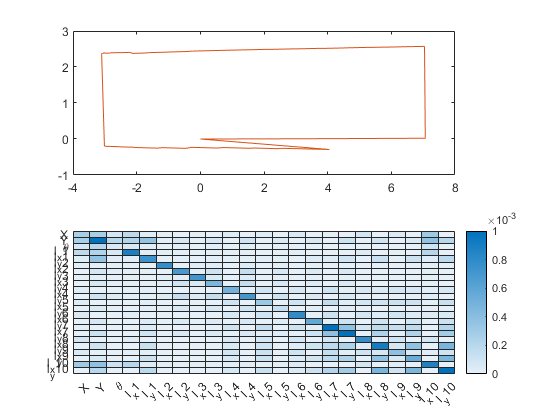

%Figures for checking
f2 = figure;
subplot(2,1,1)
plot(x_k(1,:),x_k(2,:))
hold on
plot(pos_k(1,:),pos_k(2,:))
hold off
subplot(2,1,2)
h = heatmap(locations,locations,P_k);
h.ColorLimits = [0 0.001];